Juan Diego Murcia Porras

# Modelos Matemáticos 1

# Tarea 1

## Ejercicio 1

La tabla 1.1 relaciona la cantidad de cierto aditivo a un barniz con el tiempo de secado del mismo. 

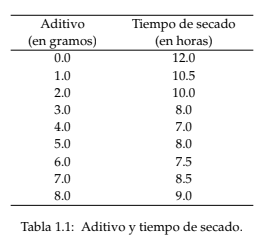

a) Escriba el sistema de ecuaciones lineales asociado al problema de encontrar el polinomio de grado menor o igual a 2 que mejor ajusta por cuadrados mínimos los datos en la Tabla 1.1.

**Solución: **Suponiendo que tal polinomio es de la forma 

$$P(x)=ax^2+bx+c$$,

$a,b$ y $c$ deben satisfacer que 

$P(x_i)=a x_i^2+bx_i+c=y_i$, para $0\leq i \leq 8$,

donde los $x_i$ representan la cantidad de aditivo en la tabla, y los $y_i
$ su tiempo de secado. Así, obtenemos el sistema de ecuaciones

$\left \{ \begin{array}{rcl} 
a (0.0)^2+b(0.0)+c &=&12.0\\
 a (1.0)^2+b(1.0)+c& =&10.5 \\
a (2.0)^2+b(2.0)+c &=&10.0 \\ 
a (3.0)^2+b(3.0)+c &=&8.0 \\
a (4.0)^2+b(4.0)+c &=&7.0 \\
a (5.0)^2+b(5.0)+c &=&8.0 \\
a (6.0)^2+b(6.0)+c &=&7.5 \\
a (7.0)^2+b(7.0)+c &=&8.5 \\
a (8.0)^2+b(8.0)+c &=&9.0 \\
\end{array}  \right.$.

b) Escriba un rutero de Matlab en el que se haga lo siguiente:

- Construya la matriz $\textbf{A}$ y parte derecha $\textbf{y}$ del sistema escrito por usted en 1.1

- Resuelva el sistema $\textbf{A}c=\textbf{y}$ en el sentido de los mínimos cuadrados.

- Grafique en un mismo gráfico los pares en la tabla y el ploinomio obtenido (evaluado en 100 puntos entre 0 y 8 y con ayuda de ployval).

**Solución: **Primero, definamos la matriz $\textbf{A}$y el vector $\textbf{y}$ pedidos

A=[0^2 0 1; 1^2 1 1; 2^2 2 1; 3^2 3 1; 4^2 4 1; 5^2 5 1; 6^2 6 1; 7^2 7 1; 8^2 8 1];
y=[12; 10.6; 10; 8; 7; 8; 7.5; 8.5; 9];

Ahora, resolvemos el sistema pedido en sentido de los mínimos cuadrados (como lo tiene Mathlab por defecto). Se muestra también el error cuadrático de tal estimación.

c=A\y

c =     0.1837
   -1.8576
   12.2230


Error_cuad=norm(y-A*c)

Error_cuad = 1.2669

Posteriormente, se grafican los pares de puntos y el polinomio obtenido.

x=linspace(0,8,100)

x =          0    0.0808    0.1616    0.2424    0.3232    0.4040    0.4848    0.5657    0.6465    0.7273    0.8081    0.8889    0.9697    1.0505    1.1313    1.2121    1.2929    1.3737    1.4545    1.5354    1.6162    1.6970    1.7778    1.8586    1.9394    2.0202    2.1010    2.1818    2.2626    2.3434    2.4242    2.5051    2.5859    2.6667    2.7475    2.8283    2.9091    2.9899    3.0707    3.1515    3.2323    3.3131    3.3939    3.4747    3.5556    3.6364    3.7172    3.7980    3.8788    3.9596


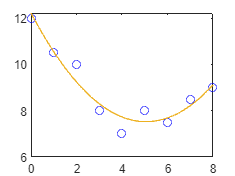

plot(0,12,'ob')
hold on
plot(1,10.5,'ob')
plot(2,10,'ob')
plot(3,8,'ob')
plot(4,7,'ob')
plot(5,8,'ob')
plot(6,7.5,'ob')
plot(7,8.5,'ob')
plot(8,9,'ob')
plot(x,polyval(c,x))
hold off

- Basados en el polinomio resultante, ¿qué cantidad de aditivo resulta en tiempo mínimo de secado?¿cuál es el tiempo mínimo de secado?

**Solución: **Como el polinomio es cuadrático y su amplitud es mayor a cero, basta con calcular el vértice del polinomio para resolver este problema. 

PM=[-c(2)/(2*c(1)); polyval(c,-c(2)/(2*c(1)))]

PM =     5.0572
    7.5259


Por lo tanto, según el modelo propuesto, 5.0572 gramos de aditivo resultan en un tiempo mínimo de secado de 7.5259 horas.

## Ejercicio 3

Las cifras de la tabla 1.3 son datos sobre el procentaje de llantas radiales producidas por cierto fabricante que aún pueden usarse después de recorrer cierto número de millas.

Se desea ajustar los datos de dicha tabla a los siguientes modelos en el sentido de los mínimos cuadrados:

$y_a(x)=\alpha \beta ^x$ e $y_b(x)=\alpha (100-x)10^{\beta x}$

Escriba un rutero en MATLAB que ejecute las siguientes tareas:

a) Determine los parámetros $\alpha$ y $\beta$ que ajustan ambos modelos a los datos de la tabla en el sentido de los mínimos cuadrados. Su programa debe mostrar estos parámetros.

**Solución: **Para el primer modelo, podemos aplicar la función $ln(\cdot)$ a ambos de la igualdad, y así obtener que 


$$ln(\alpha)+ln(\beta)\cdot x=ln(y_\alpha)$$


Por lo tanto, reemplazando cada dato $x_i$ por los miles de millas recorridas y $(y_\alpha)_i$ por el porcentaje útil ($1\leq i\leq 8$), y sustituyendo $c_1=ln(\alpha)$ y $c_2=ln(\beta)$, obtenemos que


$$\left \{ \begin{array}{rcl} 
c_1+1c_2  &=& ln(99)\\
c_1+2c_2  &=& ln(95)\\
c_1+5c_2  &=& ln(85)\\
c_1+15c_2  &=& ln(15)\\
c_1+25c_2  &=& ln(30)\\
c_1+30c_2  &=& ln(24)\\
c_1+35c_2  &=& ln(20)\\
c_1+40c_2 &=& ln(15)
\end{array}  \right.$$


O, de otra forma, el sistema dado por


$$\textbf{A}c=\textbf{y} \rightarrow$$

$$\left\lbrack \begin{array}{cc}
1 & 1\\
1 & 2\\
1 & 5\\
1 & 15\\
1 & 25\\
1 & 30\\
1 & 35\\
1 & 40
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
c_1 \\
c_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\ln \left(99\right)\\
\ln \left(95\right)\\
\ln \left(85\right)\\
\ln \left(15\right)\\
\ln \left(30\right)\\
\ln \left(24\right)\\
\ln \left(20\right)\\
\ln \left(15\right)
\end{array}\right\rbrack$$


Resolviéndolo en MATLAB,

A1=[[1 1 1 1 1 1 1 1]' [1 2 5 15 25 30 35 40]'];
y1=log([99 95 85 15 30 24 20 15]');
x1=A1\y1;
alpha1=exp(x1(1))

alpha1 = 85.2017

beta1=exp(x1(2))

beta1 = 0.9554

Por otro lado, para la segunda función planteada, aplicando la función $ln(\cdot)$ a ambos lados, obtenemos que 


$$ln(\alpha)+ln(100-x)+\beta \cdot ln (10) \cdot x=ln(y_b)$$


O, de otra manera,


$$ln(\alpha)+x\cdot ln (10) \cdot \beta=ln(y_b)-ln(100-x)$$


Reemplazando los datos de la tabla de manera similar a con $y_a$, y realizando las sustituciones $c_1=ln(\alpha)$ y $c_1=\beta$, obtenemos el sistema


$$\left \{ \begin{array}{rcl} 
c_1+(1)\cdot ln(10)\cdot c_2  &=& ln(99)-ln(100-1)\\
c_1+(2)\cdot ln(10)\cdot c_2  &=& ln(95)-ln(100-2)\\
c_1+(5)\cdot ln(10)\cdot c_2  &=& ln(85)-ln(100-5)\\
c_1+(15)\cdot ln(10)\cdot c_2  &=& ln(55)-ln(100-15)\\
c_1+(25)\cdot ln(10)\cdot c_2  &=& ln(30)-ln(100-25)\\
c_1+(30)\cdot ln(10)\cdot c_2  &=& ln(24)-ln(100-30)\\
c_1+(35)\cdot ln(10)\cdot c_2  &=& ln(20)-ln(100-35)\\
c_1+(40)\cdot ln(10)\cdot c_2  &=& ln(15)-ln(100-40)\\
\end{array}  \right.$$


Realizando un procedimiento análogo al anterior, resolvemos el sistema en cuestión.

A2=[[1 1 1 1 1 1 1 1]' log(10)*[1 2 5 15 25 30 35 40]'];
y2=log([99 95 85 55 30 24 20 15]')-log([100-1 100-2 100-5 100-15 100-25 100-30 100-35 100-40]');
x2=A2\y2;
alpha2=exp(x2(1))

alpha2 = 1.0525

beta2=x2(2)

beta2 = -0.0157

b) Para ambos modelos, muestre $||\textbf{b}-\textbf{A}x||_2$ del sistema $\textbf{A}x=\textbf{b}$ que su programa resuelve.

**Solución: **Calculemos ambas normas.

v1=norm(y1-A1*x1)

v1 = 1.1343

v2=norm(y2-A2*x2)

v2 = 0.1026

Por lo tanto, el mejor modelo (según la norma euclidea) es el segundo.

c) Dibuje en un mismo gráfico los datos de la tabla y ambos modelos ajustados.

**Solución:**

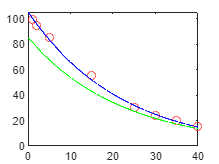

x=linspace(0,40,1000);
plot(1,99,'or')
hold on
plot(2,95,'or')
plot(5,85,'or')
plot(15,55,'or')
plot(25,30,'or')
plot(30,24,'or')
plot(35,20,'or')
plot(40,15,'or')
plot(x, alpha1* beta1.^(x),'g')
plot(x, alpha2.*(100-x).*10.^(beta2*x),'b')
hold off

d) Con el mejor modelo, estime qué porcentaje de las llantas radiales del fabricante durarán 45000 millas y 50000 millas. Su programa debe mostrar estas estimaciones.

**Solución: **Usando el segundo modelo, estimemos ambos valores.

est_1=alpha2.*(100-45).*10.^(beta2*45)

est_1 = 11.3532

est_2=alpha2.*(100-50).*10.^(beta2*50)

est_2 = 8.6123

Por ende, con este modelo se estima que aproximadamente el 11.3% de las llantas radiales durarán 45000 millas, y el 8.61% durarán 50000.

## Ejercicio 5

La tabla muestra la concentración de iones $n$ como una función del tiempo transcurrido después de haber apagado a un agente de ionización. Se sabe que se cumple la siguiente relación entre la concentración de iones y el tiempo


$$n=\frac{n_0}{1+n_0\alpha t}$$


donde $n_0$ es la concentración inicial de iones y $\alpha$, el coeficiente de recombinación.

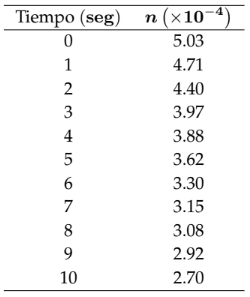

a) Muestre que existe una relación lineal entre $n^{-1}$ y $t$.

**Demostración:** Tenemos que 


$$1+n_0\alpha t=\frac{n_0}{n}$$


y, por consiguiente, 


$$1=n_0\cdot (n^{-1})- n_0 \alpha \cdot (t)$$


Por lo tanto, existe una relación lineal entre ambas variables.

b) Encuentre la función (1) que mejor ajusta por cuadrados mínimos a los datos en la tabla. Escriba las aproximaciones de $n_0$ y $\alpha$ obtenidas.

**Solución: **Utilizando la demostración del literal a), podemos concluir que 


$$\frac{1}{n_0}+\alpha t= \frac{1}{n}$$


Utilizando los datos de la tabla, $c_1=\frac{1}{n_0}$ y $c_2=\alpha$, obtenemos el sistema


$$\left \{ \begin{array}{rcl} 
c_1+0 c_2 &=& \frac{1}{5.03}\\
c_1+1 c_2 &=& \frac{1}{4.71}\\
c_1+2 c_2 &=& \frac{1}{4.40}\\
c_1+3 c_2 &=& \frac{1}{3.97}\\
c_1+4 c_2 &=& \frac{1}{3.88}\\
c_1+5 c_2 &=& \frac{1}{3.62}\\ 
c_1+6 c_2 &=& \frac{1}{3.30}\\ 
c_1+7 c_2 &=& \frac{1}{3.15}\\ 
c_1+8 c_2 &=& \frac{1}{3.08}\\ 
c_1+9 c_2 &=& \frac{1}{2.92}\\ 
c_1+10 c_2 &=& \frac{1}{2.70}\\ 
\end{array}  \right. $$


Resolvamos este sistema en MATLAB.

A=[[1 1 1 1 1 1 1 1 1 1 1]' [0 1 2 3 4 5 6 7 8 9 10]'];
y=1./[5.03 4.71 4.4 3.97 3.88 3.62 3.3 3.15 3.08 2.92 2.7]';
x=A\y;
Error_cuadratico=norm(y-A*x)

Error_cuadratico = 0.0154

n_0=1/x(1)

n_0 = 5.0956

alpha=x(2)

alpha = 0.0168

Por lo tanto, usando el método de mínimos cuadrados, $n_0=5.096$ y $\alpha=0.017$. El error cuadrático de la solución del sistema lineal asociado es de $0.0154$.

c) Grafique los pares ordenados en la tabla y la función $n$ obtenida (evaluada en 110 puntos de 0 a 10).

**Solución:**

x=linspace(0,10,110)

x =          0    0.0917    0.1835    0.2752    0.3670    0.4587    0.5505    0.6422    0.7339    0.8257    0.9174    1.0092    1.1009    1.1927    1.2844    1.3761    1.4679    1.5596    1.6514    1.7431    1.8349    1.9266    2.0183    2.1101    2.2018    2.2936    2.3853    2.4771    2.5688    2.6606    2.7523    2.8440    2.9358    3.0275    3.1193    3.2110    3.3028    3.3945    3.4862    3.5780    3.6697    3.7615    3.8532    3.9450    4.0367    4.1284    4.2202    4.3119    4.4037    4.4954


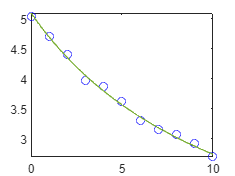

plot(0,5.03,'ob')
hold on
plot(1,4.71,'ob')
plot(2,4.4,'ob')
plot(3,3.97,'ob')
plot(4,3.88,'ob')
plot(5,3.62,'ob')
plot(6,3.30,'ob')
plot(7,3.15,'ob')
plot(8,3.08,'ob')
plot(9,2.92,'ob')
plot(10, 2.70,'ob')
plot(x, n_0./(1+(n_0.*alpha.*x)))
hold off